clear;
clc;

Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;
Rohm=0.0050398;
% Rohm=1.2e-3;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

I=-17.5*[ones(2000,1);zeros(300,1);-ones(2000,1);zeros(3700,1)];

Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;

socn=soc0n+cumsum(I/3600/Qn);
socp=soc0p-cumsum(I/3600/Qp);

三参数抛物线近似

tic;
dcn=three_parameter(Dsn,Rsn,Jn);
dcp=three_parameter(Dsp,Rsp,Jp);

socsurfn_three=dcn/csmaxneg+socn;
socsurfp_three=dcp/csmaxpos+socp;

TPM_V=EeqLMO(socsurfp_three)-EeqC(socsurfn_three)+I*Rohm;
toc;

历时 0.960920 秒。


分数阶Pade近似

tic;
dcsep=fom(Rsp,Dsp,Jp);
dcsen=fom(Rsn,Dsn,Jn);

socsurfp_fom=dcsep/csmaxpos+socp;
socsurfn_fom=dcsen/csmaxneg+socn;

FOM_V=EeqLMO(socsurfp_fom)-EeqC(socsurfn_fom)+I*Rohm;
toc;

历时 1.209030 秒。


DRA近似

Ds=Dsn;
Rs=Rsn;

F1=256;%采样频率
T1=1/F1;%采样周期
minTlen=256;
N=2^(ceil(log2(minTlen*F1)));
f=0:N-1;
s=(2j/T1)*tan(pi*f/N);

beta=Rs*sqrt(s/Ds);
Hd=Rs/Ds*(1./(1-beta.*coth(beta)))+(3/Rs)./s;
Hd(1)=-Rs/5/Ds;
hd=real(ifft(Hd))*F1;
td=T1*(0:N-1);

hstep=T1*cumsum(hd);

Ts=1;
tdisc=0:Ts:256;
hdisc=[0 diff(interp1(td,hstep,tdisc))];

bigHankel=hankel(hdisc(2:257));
Hankel=bigHankel(1:127,1:127);
HankelUp=bigHankel(2:128,1:127);
[U,S,V]=svd(Hankel);

n=2;
Us=U(:,1:n);
Ss=S(1:n,1:n);
Vs=V(:,1:n);
ok=Us*sqrtm(Ss);
cl=sqrtm(Ss)*Vs';

Ahat=(ok\HankelUp)/cl;
Bhat=cl(1:n,1);
Chat=-ok(1,1:n);
Dhat=0;
sysDRA = ss(Ahat,Bhat,Chat,Dhat,Ts);

% [cseTilde,tk]=lsim(sysDRA,Jp);
tic;
csepTilde=DRA(Rsp,Dsp,Jp);
csenTilde=DRA(Rsn,Dsn,Jn);

socsurfp_dra=csepTilde/csmaxpos+socp;
socsurfn_dra=csenTilde/csmaxneg+socn;

DRA_V=EeqLMO(socsurfp_dra)-EeqC(socsurfn_dra)+I*Rohm;
toc;

历时 0.094822 秒。


P2D模型数据导入


load p2d_LMO_socnsurf.txt;
load p2d_LMO_socpsurf.txt;
load p2d_LMO_V.txt;

p2d_socpsurf=p2d_LMO_socpsurf(:,2);
p2d_socnsurf=p2d_LMO_socnsurf(:,2);
P2D_V=p2d_LMO_V(:,2);

p2d_dcsen=(p2d_socnsurf-socn)*csmaxneg;
p2d_dcsep=(p2d_socpsurf-socp)*csmaxpos;

误差对比

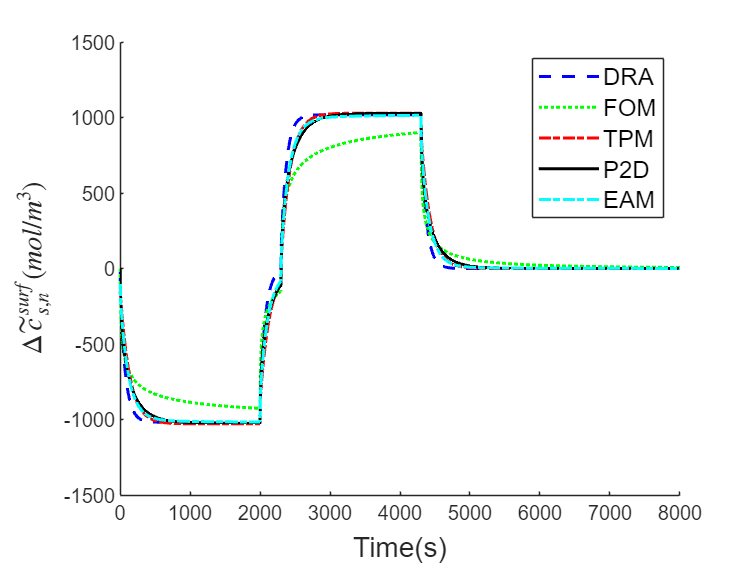

xn=[0.21651,0.093326];
k1=xn(1);
k2=xn(2);
k3=1-k1-k2;

ensemblen=k1*csenTilde+k2*dcsen+k3*dcn;

figure(1);
clf;
hold on;
plot(csenTilde,'b--','LineWidth',1.5);
plot(dcsen,'g:','LineWidth',1.5);
plot(dcn,'r-.','LineWidth',1.5);
plot(p2d_dcsen,'k','LineWidth',1.5);
plot(ensemblen,'c-.','LineWidth',1.5);
xlabel('Time(s)','fontsize',14);
ylabel('$\Delta \tilde c_{s,n}^{surf} (mol/m^3)$','Interpreter','latex','fontsize',14);
legend('DRA','FOM','TPM','P2D','EAM','fontsize',12);

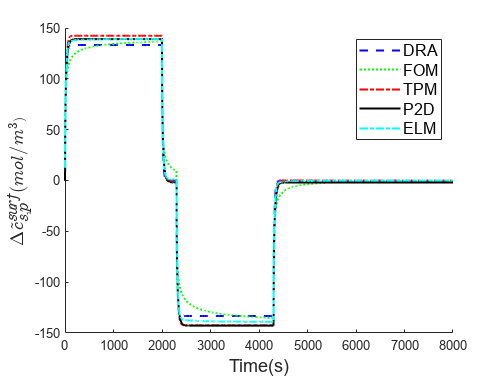

thetan_error(1,1)=RMSE(csenTilde,p2d_dcsen);
thetan_error(1,2)=RMSE(dcsen,p2d_dcsen);
thetan_error(1,3)=RMSE(dcn,p2d_dcsen);
thetan_error(1,4)=RMSE(ensemblen,p2d_dcsen);

thetan_error(2,1)=MAPE(csenTilde,p2d_dcsen);
thetan_error(2,2)=MAPE(dcsen,p2d_dcsen);
thetan_error(2,3)=MAPE(dcn,p2d_dcsen);
thetan_error(2,4)=MAPE(ensemblen,p2d_dcsen);

xp=[0.2867 0.099828];
k1=xp(1);
k2=xp(2);
k3=1-k1-k2;

ensemblep=k1*csepTilde+k2*dcsep+k3*dcp;

figure(2);
clf;
hold on;
plot(csepTilde,'b--','LineWidth',1.5);
plot(dcsep,'g:','LineWidth',1.5);
plot(dcp,'r-.','LineWidth',1.5);
plot(p2d_dcsep,'k','LineWidth',1.5);
plot(ensemblep,'c-.',LineWidth=1.5);
xlabel('Time(s)','fontsize',14);
ylabel('$\Delta \tilde c_{s,p}^{surf} (mol/m^3)$','Interpreter','latex','fontsize',14);
legend('DRA','FOM','TPM','P2D','ELM','fontsize',12);

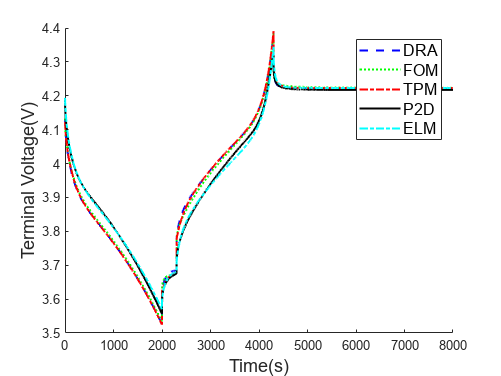

thetap_error(1,1)=RMSE(csepTilde,p2d_dcsep);
thetap_error(1,2)=RMSE(dcsep,p2d_dcsep);
thetap_error(1,3)=RMSE(dcp,p2d_dcsep);
thetap_error(1,4)=RMSE(ensemblep,p2d_dcsep);

thetap_error(2,1)=MAPE(csepTilde,p2d_dcsep);
thetap_error(2,2)=MAPE(dcsep,p2d_dcsep);
thetap_error(2,3)=MAPE(dcp,p2d_dcsep);
thetap_error(2,4)=MAPE(ensemblep,p2d_dcsep);

socsurfp_eam=ensemblep/csmaxpos+socp;
socsurfn_eam=ensemblen/csmaxneg+socn;
ELM_OCV=EeqLMO(socsurfp_eam)-EeqC(socsurfn_eam);

load V_cc.txt;
P2D_V2=V_cc(:,2);

% setting = optimoptions('particleswarm','SwarmSize',500,'Display','iter','MaxIterations',500);
% [Rohm,evalu] = particleswarm(@findRohm,1,[0],[0.1],setting)
t_plus=0.363;
Rg=8.314;
T=298.15;
Rohm_ce=1.2e-3;
[spe_cen,spe_cep]=sp_electrolyte(I);
ELM_v_ce=(1+t_plus)*2*Rg*T/F*log(spe_cep'./spe_cen');

EAM_V=EeqLMO(socsurfp_eam)-EeqC(socsurfn_eam)+I*Rohm_ce+ELM_v_ce;

figure(3);
clf;
hold on;
plot(DRA_V,'b--','LineWidth',1.5);
plot(FOM_V,'g:','LineWidth',1.5);
plot(TPM_V,'r-.','LineWidth',1.5);
plot(P2D_V2,'k','LineWidth',1.5);
plot(EAM_V,'c-.','LineWidth',1.5);
xlabel('Time(s)','fontsize',14);
ylabel('Terminal Voltage(V)','fontsize',14);
legend('DRA','FOM','TPM','P2D','ELM','fontsize',12);

V_error(1,1)=RMSE(DRA_V,P2D_V2);
V_error(1,2)=RMSE(FOM_V,P2D_V2);
V_error(1,3)=RMSE(TPM_V,P2D_V2);
V_error(1,4)=RMSE(EAM_V,P2D_V2);

V_error(2,1)=MAPE(DRA_V,P2D_V2);
V_error(2,2)=MAPE(FOM_V,P2D_V2);
V_error(2,3)=MAPE(TPM_V,P2D_V2);
V_error(2,4)=MAPE(EAM_V,P2D_V2);